# DatFin Assignment 1g and 1h for optimally weighted (results imported from Python implementation) portfolio for timeframe 2011-2021

clear all; close all;

if ~exist('stocks', 'var')
    stocks = hist_stock_data('01012011','01012021', {'XLE', 'XLF', 'XLV', 'XLI', 'XLP', 'XLK', 'XLU','^GSPC'}, 'frequency', 'mo');
    
    XLE = stocks(1).AdjClose;
    XLF = stocks(2).AdjClose;
    XLV = stocks(3).AdjClose;
    XLI = stocks(4).AdjClose;
    XLP = stocks(5).AdjClose;
    XLK = stocks(6).AdjClose; 
    XLU = stocks(7).AdjClose;
end

names_tmp = string({stocks.Ticker});
names = names_tmp(1:7)

names = 1×7 string array
    "XLE"    "XLF"    "XLV"    "XLI"    "XLP"    "XLK"    "XLU"


num_stocks = length(names);

XLELR   = log(XLE(2:end)./ XLE(1:end-1));
XLFLR   = log(XLF(2:end)./ XLF(1:end-1));
XLVLR   = log(XLV(2:end)./ XLV(1:end-1));
XLILR   = log(XLI(2:end)./ XLI(1:end-1));
XLPLR   = log(XLP(2:end)./ XLP(1:end-1));
XLKLR   = log(XLK(2:end)./ XLK(1:end-1));
XLULR   = log(XLU(2:end)./ XLU(1:end-1));

LogReturns = [XLELR, XLFLR, XLVLR, XLILR, XLPLR, XLKLR, XLULR];
yearlycov = 12 * cov(LogReturns)'; %12 months a year

% Market data
if ~exist('SP', 'var')
    % S&P 500 index as 'market'
    SP = hist_stock_data('01012011','01012021', '^GSPC', 'frequency', 'mo');    
    
    SPLR = log(SP.AdjClose(2:end) ./ SP.AdjClose(1:end-1));
    market_mean = 12 * mean(SPLR); 
    market_std  = sqrt(12) * std(SPLR);
    market_var  = 12 * cov(SPLR); 
end
% Apply single index model to estimate betas (and alphas)
mdl_si = cell(num_stocks, 1); 
alpha_s = [];
beta_s  = [];

for i = 1:num_stocks
    mdl_si{i} = fitlm(SPLR, LogReturns(:,i));
   
    % Total covariance based on the single index model (sigma^2_ei)
    mdl_cov_s(i) =  mdl_si{i}.MSE;
    
    % Alpha and beta arrays
    alpha_s = [alpha_s, mdl_si{i}.Coefficients.Estimate(1)];
    beta_s  = [beta_s, mdl_si{i}.Coefficients.Estimate(2)];
end

% Sharpe optimised portfolio weights (imported from Python code results)
x = [0.006204, 0.015758, 0.342502, 0.015786, 0.095952, 0.375988, 0.147810] 

x =     0.0062    0.0158    0.3425    0.0158    0.0960    0.3760    0.1478


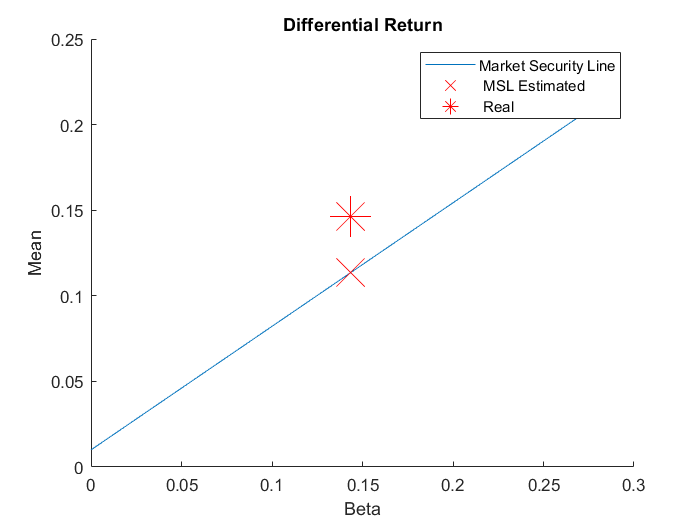

% Single model index estimation
% portfolio expected return (EGBG, page 135)
exp_ret = x * alpha_s' + x * beta_s' * market_mean;

% Portfolio variance (EGBG, page 134, 3rd equation)
% (x_1 beta_1, ... , \x_n beta_n)
xibi = x .* beta_s;

% \sigma^2_m sum (x_i beta_i)
sxibism = sum(xibi) * market_var;

% ((x_1)^2, ..., (x_n)^2)
x2 = x.^2;

% sum ((x_1)^2 , ..., (x_n)^2)
xi2sei = sum(x2 .*  mdl_cov_s);

% sum (  (x_1 beta_1, ..., x_n beta_n) ) \sigma^2_m sum (x_i beta_i)
%       + sum ((x_1)^2 mdl_si{1}.MSE, ..., (x_n)^2 mdl_si{n}.MSE) 
sig_p2_s = sum(xibi) * sxibism + xi2sei;
% Real mean and variance
yearlymean = x * (12 * mean(LogReturns)');
yearlyvar = x * yearlycov * x';
indices_std  = x * (sqrt(12) * std(LogReturns)');
% Market Slope
Rf =  0.01; % Risk-free rate
figure;
MSL = (market_mean - Rf) / market_std;
line([0, market_std, (2 * market_std)], [Rf market_mean, (2 * market_mean - Rf)],'DisplayName','Market Security Line');

% Plot two points for each index: expected return estimated using 
% market security line (MSL) and real return of index.
col = hsv(1);
diff_rets = Rf + MSL .* indices_std;
hold on;
plot(indices_std, diff_rets, 'rx', 'color',  col,'DisplayName',' MSL Estimated','MarkerSize',24); 
hold on;
plot(indices_std, yearlymean, '*', 'color', col,'DisplayName',' Real','MarkerSize',24); 

hold on;
title('Differential Return');
xlabel('Beta');
ylabel('Mean');
legend();%(k, names);
hold off;

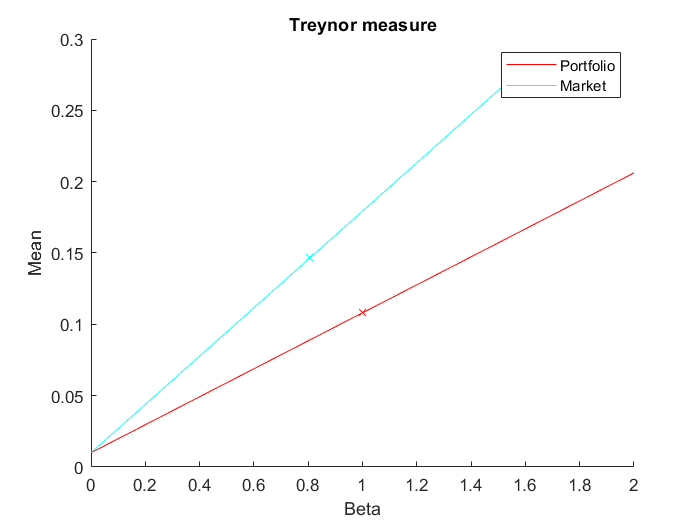

LRS = (x * LogReturns')';
indices_mean = yearlymean;
RmtmRft = SPLR - Rf;
X = [ones(length(RmtmRft), 1), RmtmRft];

b = cell(2, 1);
bint = cell(2, 1);
stats = cell(2, 1);
rint = cell(2, 1);
r = cell(2, 1);
RitmRft = cell(1);

LRS_wm = [SPLR, LRS];
means = [market_mean, indices_mean];

% Linear fit using market and index returns to estimate betas
for i=1:2
    RitmRft{i} = LRS_wm(:,i) - Rf;
    [b{i}, bint{i}, r{i}, rint{i}, stats{i}] = regress(RitmRft{i}, X);
end

% Change to look at the line over beta, instead of sigma (standard deviation)
figure;
col = hsv(2);
for i = 1:2
    hold on;
    h(i) = plot(b{i}(2), means(i) , 'rx', 'color', col(i,:)); 
    hold on;
    h(i) = line([0, b{i}(2), (2 * b{i}(2))], [Rf, means(i), (2 * means(i) - Rf)], 'color', col(i,:));
    hold on;
end

hold on;
title('Treynor measure');
xlabel('Beta');
ylabel('Mean');
legend(h, {"Portfolio","Market"});
hold off;

for i = 1:2
    JA(i) = indices_mean - Rf - b{i}(2) * (market_mean - Rf);
end

disp("Jensen's alpha:"+JA);

    "Jensen's alpha:0.038514"    "Jensen's alpha:0.057498"



RitmRft = LRS - Rf; %SPLR - Rf;
RmtmRft = SPLR - Rf;
RmtmRft2 = (SPLR - Rf).^2;

X2 = [ones(length(RmtmRft), 1), RmtmRft, RmtmRft2];
    
b = cell(1);
bint = cell(1);
stats = cell(1);
rint = cell(1);
r = cell(1);

%RitmRft{i} = LRS(:,i) - Rf; % Calculated above
[b, bint, r, rint, stats] = regress(RitmRft, X2);

tmp = b;
as = tmp(1);
bs = tmp(2);
cs = tmp(3); % c_i is the third coefficient of quadratic fit
    
ptmp = stats;
ps = ptmp(end); 

disp("Timing abilty (c_i): "+cs);

Timing abilty (c_i): 0.23302


disp("Corresponding p-values: "+ps);

Corresponding p-values: 0.0001327


disp("Alpha: "+as)

Alpha: 0.0026664


disp("Beta: "+bs)

Beta: 0.8116


disp(ptmp) %"r2 F prob s2 "

    0.8847  445.2001    0.0000    0.0001



% Apply single index model to estimate betas (and alphas)
mdl_sip = fitlm(SPLR,  x * LogReturns');
% Total covariance based on the single index model (sigma^2_ei)
mdl_cov_s =  mdl_sip.MSE;

% Alpha and beta
alpha_p = mdl_sip.Coefficients.Estimate(1);
beta_p  = mdl_sip.Coefficients.Estimate(2);

stock_name = 'Portfolio';
stock_rets = x * LogReturns';
market_rets = SPLR;

disp("Model parameters:"); % If pValue <= 0.05 => statistical significance

Model parameters:


disp(mdl_sip);

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    _________    ______    __________

    (Intercept)    0.0049528    0.0010808    4.5824    1.1578e-05
    x1               0.80643      0.02696    29.912    1.2176e-56


Number of observations: 119, Error degrees of freedom: 117
Root Mean Squared Error: 0.0115
R-squared: 0.884,  Adjusted R-Squared: 0.883
F-statistic vs. constant model: 895, p-value = 1.22e-56


fprintf("\n");
figure;
hold on;
plot(market_rets, stock_rets, 'o');

alpha = alpha_p%alpha_s(stock_idx);

alpha = 0.0050

beta = beta_p%beta_s(stock_idx);

beta = 0.8064

disp("Fit line: ");

Fit line: 


disp("f(x) = " + alpha + " + " + beta + "x");

f(x) = 0.0049528 + 0.80643x


model_err = mdl_sip.MSE;
disp("R^2: " + model_err);

R^2: 0.000132


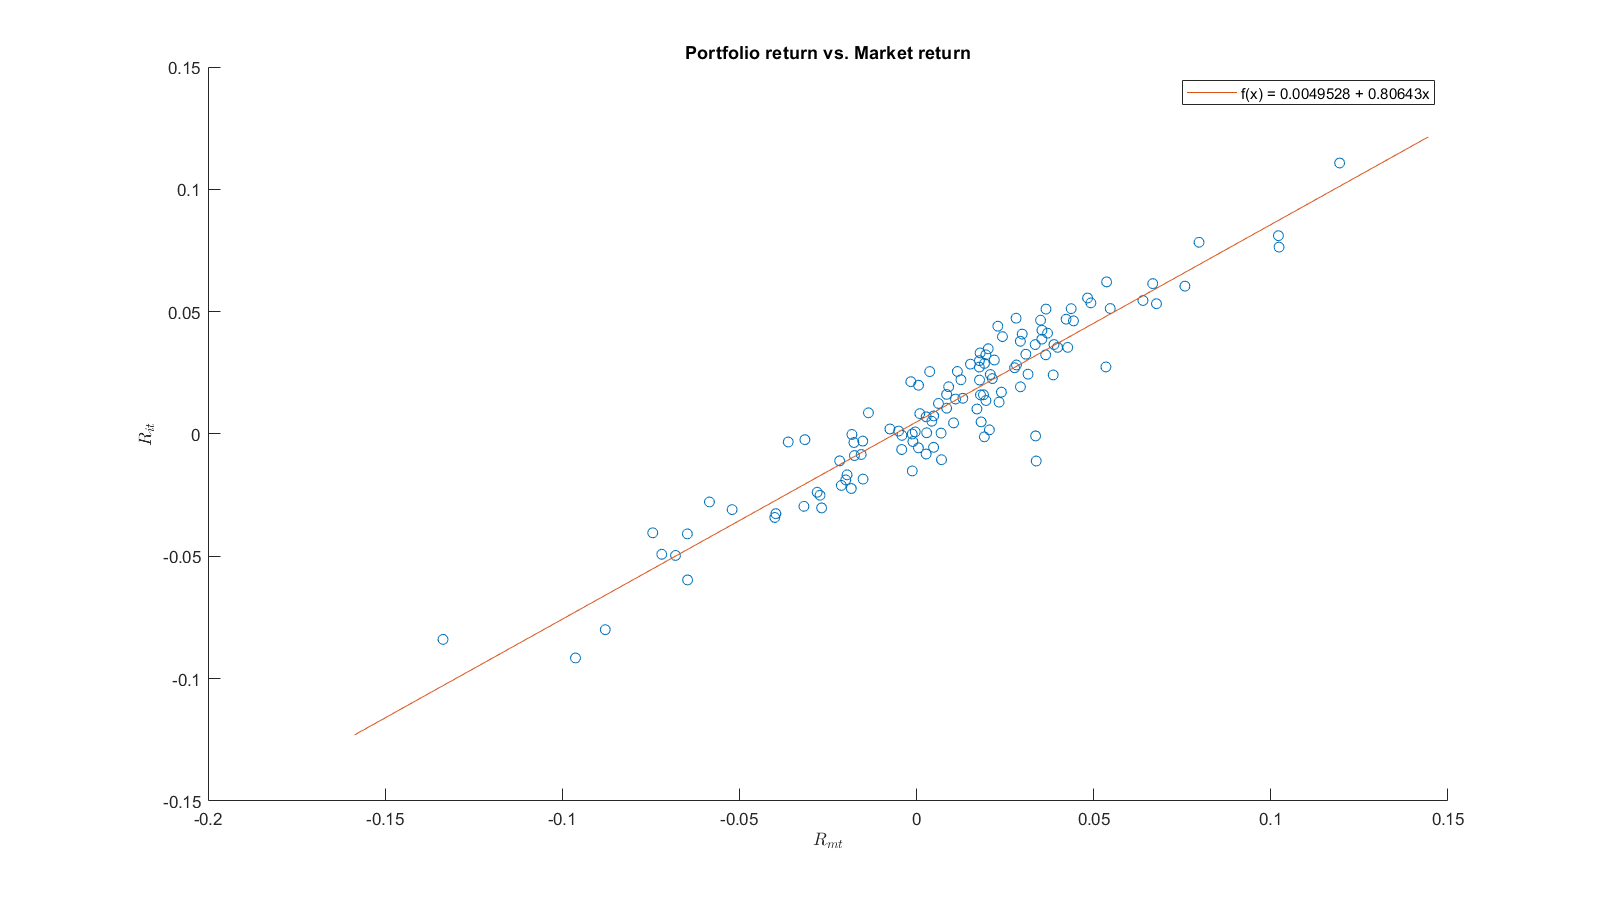

fit = @(x) (alpha + beta * x);
xmin = min(market_rets);
xmax = max(market_rets);
xoffset = 0.025;

hold on;
p1 = fplot(fit, [xmin - xoffset, xmax + xoffset]);

set(gcf,'position',[0, 0, 1280, 720])
title(stock_name+" return vs. Market return");
xlabel("$R_{mt}$", "interpreter", "latex"); 
ylabel("$R_{it}$", "interpreter", "latex");
legend([p1],"f(x) = " + alpha + " + " + beta + "x");